% try to fit this function by an interpolating polynomial by varying n_nodes
f = @(x) sqrt(x.^3 + 1);
x_vec = linspace(0,5,1000);  
n_nodes = 3; % number of equally spaced nodes to base polynomial on
x_nodes = linspace(min(x_vec),max(x_vec), n_nodes); % n_nodes equally spaced nodes spanning x_vec bounds
y_nodes = f(x_nodes); % y values of original function at nodes
p = polyfit(x_nodes,y_nodes,n_nodes-1)  % outputs coefficients of interpolating polynomial of degree n_nodes-1

p =     0.3256    0.4169    1.0000


y_interp = polyval(p,x_vec) % evaluates polynomial over densely sampled x_vec for plotting

y_interp =     1.0000    1.0021    1.0042    1.0063    1.0085    1.0106    1.0128    1.0150    1.0172    1.0194    1.0217    1.0239    1.0262    1.0285    1.0308    1.0331    1.0355    1.0378    1.0402    1.0426    1.0450    1.0474    1.0499    1.0523    1.0548    1.0573    1.0598    1.0623    1.0648    1.0674    1.0699    1.0725    1.0751    1.0777    1.0804    1.0830    1.0857    1.0884    1.0911    1.0938    1.0965    1.0993    1.1020    1.1048    1.1076    1.1104    1.1132    1.1161    1.1190    1.1218


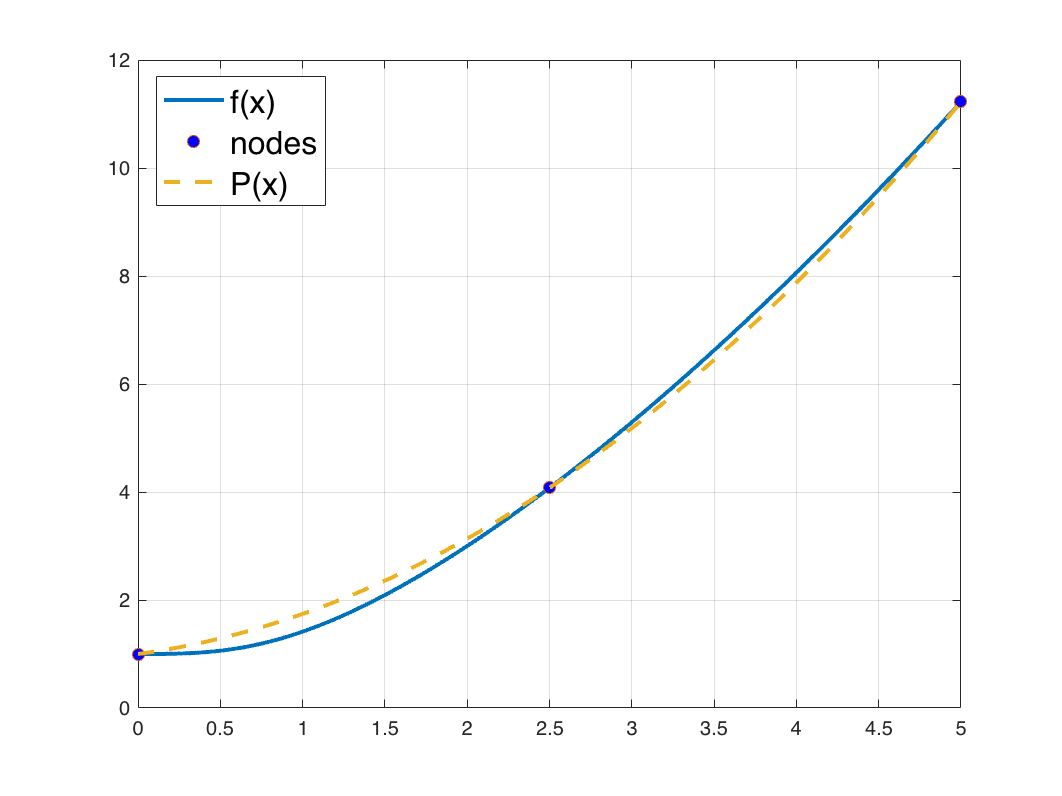

figure(38); clf
plot(x_vec,f(x_vec),'linewidth',2); grid on % plot original function
hold on % add to plot
plot(x_nodes,y_nodes,'o','MarkerFaceColor','b'); % plot nodes that polynomial goes through
plot(x_vec,y_interp,'--','LineWidth',2); %  plot interpolating polynomial
hold off % stop adding
legend('f(x)','nodes','P(x)','Location','best','fontsize',16) % input labels in order that they were plotted